# **TU: Windowing, STFT for Frequecy Features **

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Frequency Preprocessing and Features of 

- Windowing

- STFT

> Need to use  getFFT.m   

## Include path

addpath('../IAIA/Library/')  

# Windowing

We will learn how to apply hanning window

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

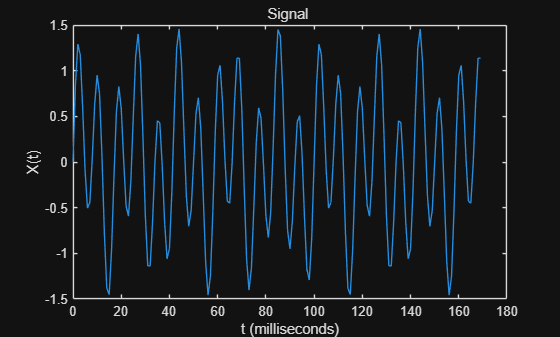

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 170;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

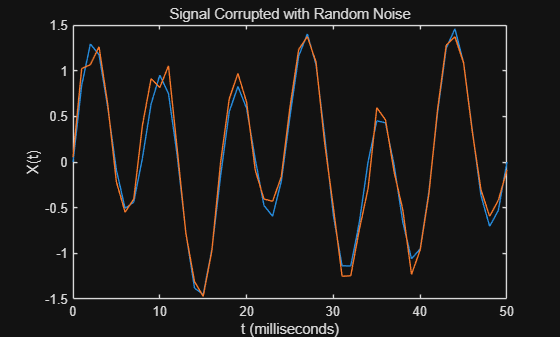



% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

## Exercise : Apply Hanning Window

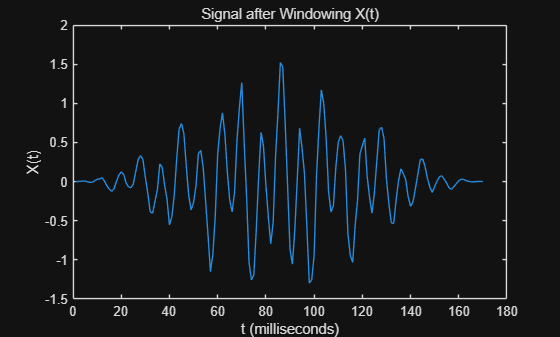

L=N;
win=hanning(L);
xm = Xm';
%%% Apply window to X by multiplication
% YOUR CODE GOES HERE
Xw=xm.*win;           %YOUR CODE

%%% single-sided spectrum P1
% YOUR CODE GOES HERE
P1=getFFT_student(Xw,L);
P2=getFFT_student(xm,L);

f = 0:Fs/L:Fs/2;


% Plot single-sided P1
figure
plot(Xw)
title('Signal after Windowing X(t)')
xlabel('t (milliseconds)')
ylabel('X(t)')

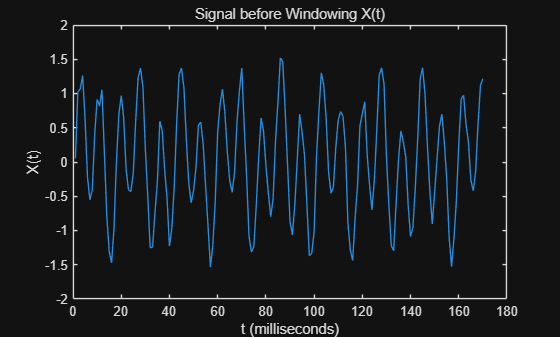


figure
plot(xm)
title('Signal before Windowing X(t)')
xlabel('t (milliseconds)')
ylabel('X(t)')

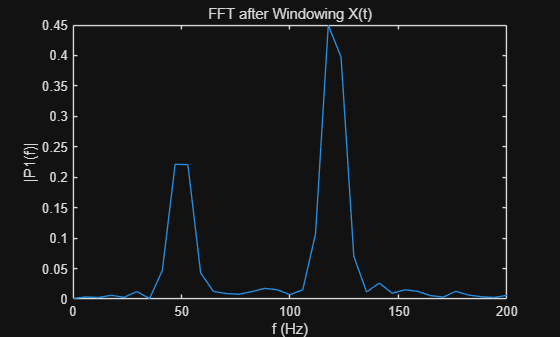


% Plot single-sided P1
figure
plot(f,P1) 
title('FFT after Windowing X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 200])

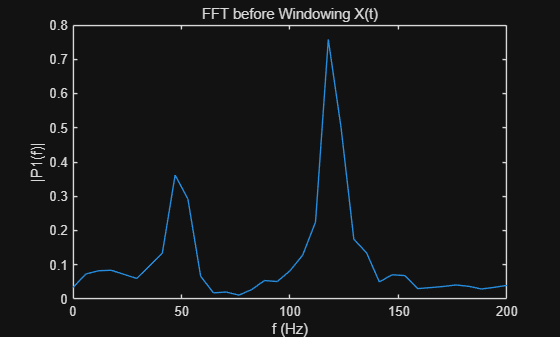

figure
plot(f,P2) 
title('FFT before Windowing X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')
xlim([0 200])

# **STFT**

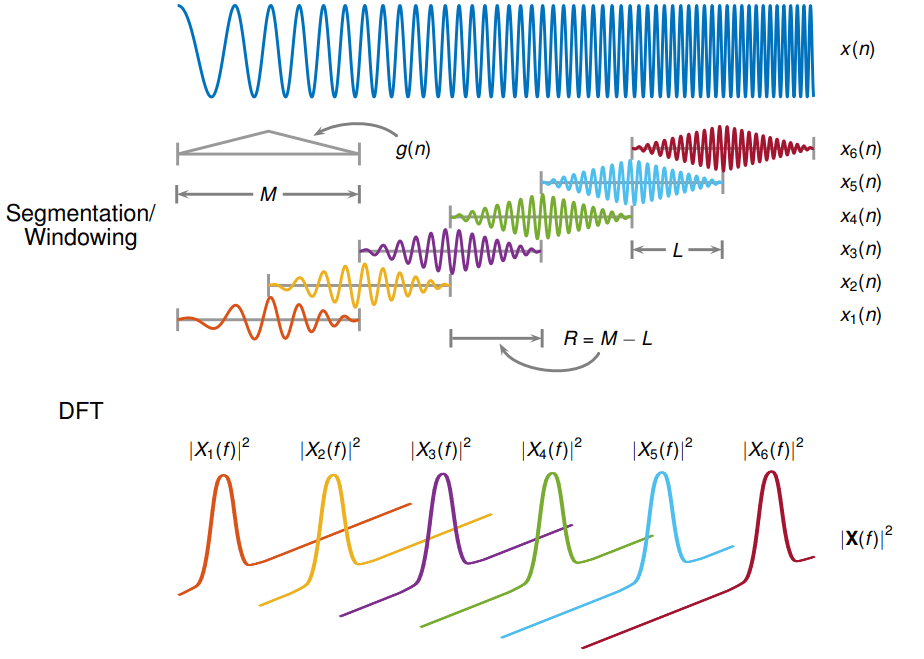

## Dataset

### Generate Signals

A chirp signal from 100 to 200 Hz in 2 secods

ts = 0:1/1e3:2;
f0 = 100;
f1 = 200;

x = chirp(ts,f0,1,f1,'quadratic',[],'concave');
% x = chirp(ts,f0,1,f1);

## Exercise : STFT - one-sided

Compute and display the STFT of the quadratic chirp with a duration of 1 ms.

- Fs= 1000Hz.

- Divide Segments with 128 data points

- STFT Overlap of 50 datapoints

- DFT length as 128(default) with Hamming window 

fs=1e3;
win = hamming(128,"periodic");


%%% YOUR CODE GOES HERE
[S,F,T] = stft(x, fs, Window = win, OverlapLength = 50, FFTLength = 128) %YOUR CODE

S =    0.0223 + 0.0003i  -0.0184 - 0.0004i  -0.0518 - 0.0007i   0.0132 + 0.0003i   0.0152 - 0.0003i   0.0671 + 0.0022i   0.0611 + 0.0009i   0.0858 + 0.0021i  -0.0266 - 0.0003i  -0.0704 - 0.0014i   0.0214 + 0.0005i   0.0523 + 0.0022i   0.0739 + 0.0028i   0.0536 - 0.0001i  -0.0054 + 0.0006i   0.0490 - 0.0006i  -0.0365 + 0.0007i   0.0449 - 0.0029i  -0.1276 - 0.0052i  -0.1552 - 0.0050i  -0.1601 - 0.0093i  -0.0649 - 0.0058i  -0.0095 + 0.0249i   0.0329 - 0.0424i   1.2297 + 8.9994i
   0.0223 + 0.0007i  -0.0184 - 0.0008i  -0.0518 - 0.0015i   0.0132 + 0.0006i   0.0153 - 0.0007i   0.0671 + 0.0043i   0.0612 + 0.0018i   0.0858 + 0.0042i  -0.0266 - 0.0006i  -0.0705 - 0.0027i   0.0214 + 0.0010i   0.0522 + 0.0044i   0.0739 + 0.0056i   0.0538 - 0.0002i  -0.0054 + 0.0012i   0.0492 - 0.0013i  -0.0367 + 0.0014i   0.0453 - 0.0059i  -0.1280 - 0.0104i  -0.1560 - 0.0101i  -0.1612 - 0.0188i  -0.0664 - 0.0118i  -0.0105 + 0.0503i  -0.0908 - 0.2086i -17.1829 - 3.3239i
   0.0223 + 0.0010i  -0.0184 - 0.0012i  -0.0

F =  -492.1875
 -484.3750
 -476.5625
 -468.7500
 -460.9375
 -453.1250
 -445.3125
 -437.5000
 -429.6875
 -421.8750
 -414.0625
 -406.2500
 -398.4375
 -390.6250
 -382.8125


T =     0.0640
    0.1420
    0.2200
    0.2980
    0.3760
    0.4540
    0.5320
    0.6100
    0.6880
    0.7660
    0.8440
    0.9220
    1.0000
    1.0780
    1.1560


Visualize the STFT of each channel as a waterfall plot. 

Control the behavior of the axes using the helper function `helperGraphicsOpt`.

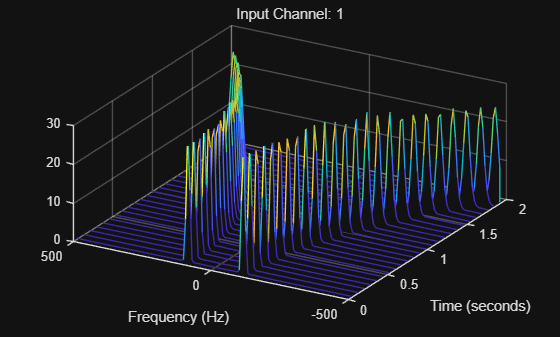

figure
waterfall(F,T,abs(S)')
helperGraphicsOpt(1)

## Exercise : STFT - Spectogram PSD

You can also use spectogram for STFT. This plots PSD of each segment.

- Fs= 1 kHz, 

- Divide segments by length of 128 samples

- Overlap of 50 samples. 

- Use 128 DFT points and the default Hamming window.

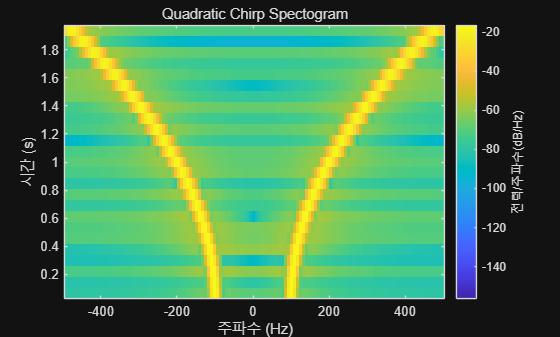

%%% YOUR CODE GOES HERE
Nsample     = 128   ;
Noverlap    = 50    ;
Ndft        = 128   ;

spectrogram(x, Nsample, Noverlap, Ndft, fs, "centered")
title('Quadratic Chirp Spectogram')

`%helperGraphicsOpt(1)`

function helperGraphicsOpt(ChannelId)
ax = gca;
ax.XDir = 'reverse';
ax.ZLim = [0 30];
ax.Title.String = ['Input Channel: ' num2str(ChannelId)];
ax.XLabel.String = 'Frequency (Hz)';
ax.YLabel.String = 'Time (seconds)';
ax.View = [30 45];
end